# Maximizing Solar Panel Output for a Fixed Area

In this project, you will use MATLAB to formulate and solve an optimization problem: Given a fixed area, determine the optimal tilt angle and aspect ratio of a solar panel to maximize the total energy output.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Define the objective function in MATLAB (the energy function).

- Use a [problem-based optimization workflow](https://www.mathworks.com/help/releases/R2026a/optim/ug/problem-based-workflow.html?searchPort=57359) to find the values of θ and r that maximize the energy output. Constrain the values: 0 ≤ θ ≤ 90 and 0.5 ≤ r ≤ 4

- Plot the objective function using `meshgrid` and [`surf`](https://www.mathworks.com/help/matlab/ref/surf.html) to visualize E(θ, r) as a 3D surface plot. Then, print the optimal angle, ratio, and corresponding energy output.

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Define the Objective Function

The energy function is the objective function for this optimization problem. It calculates how much energy a solar panel produces based on its tilt angle (theta) and aspect ratio (r). Check the Project Description for the energy formula and parameter definitions and use the image below as a guide:

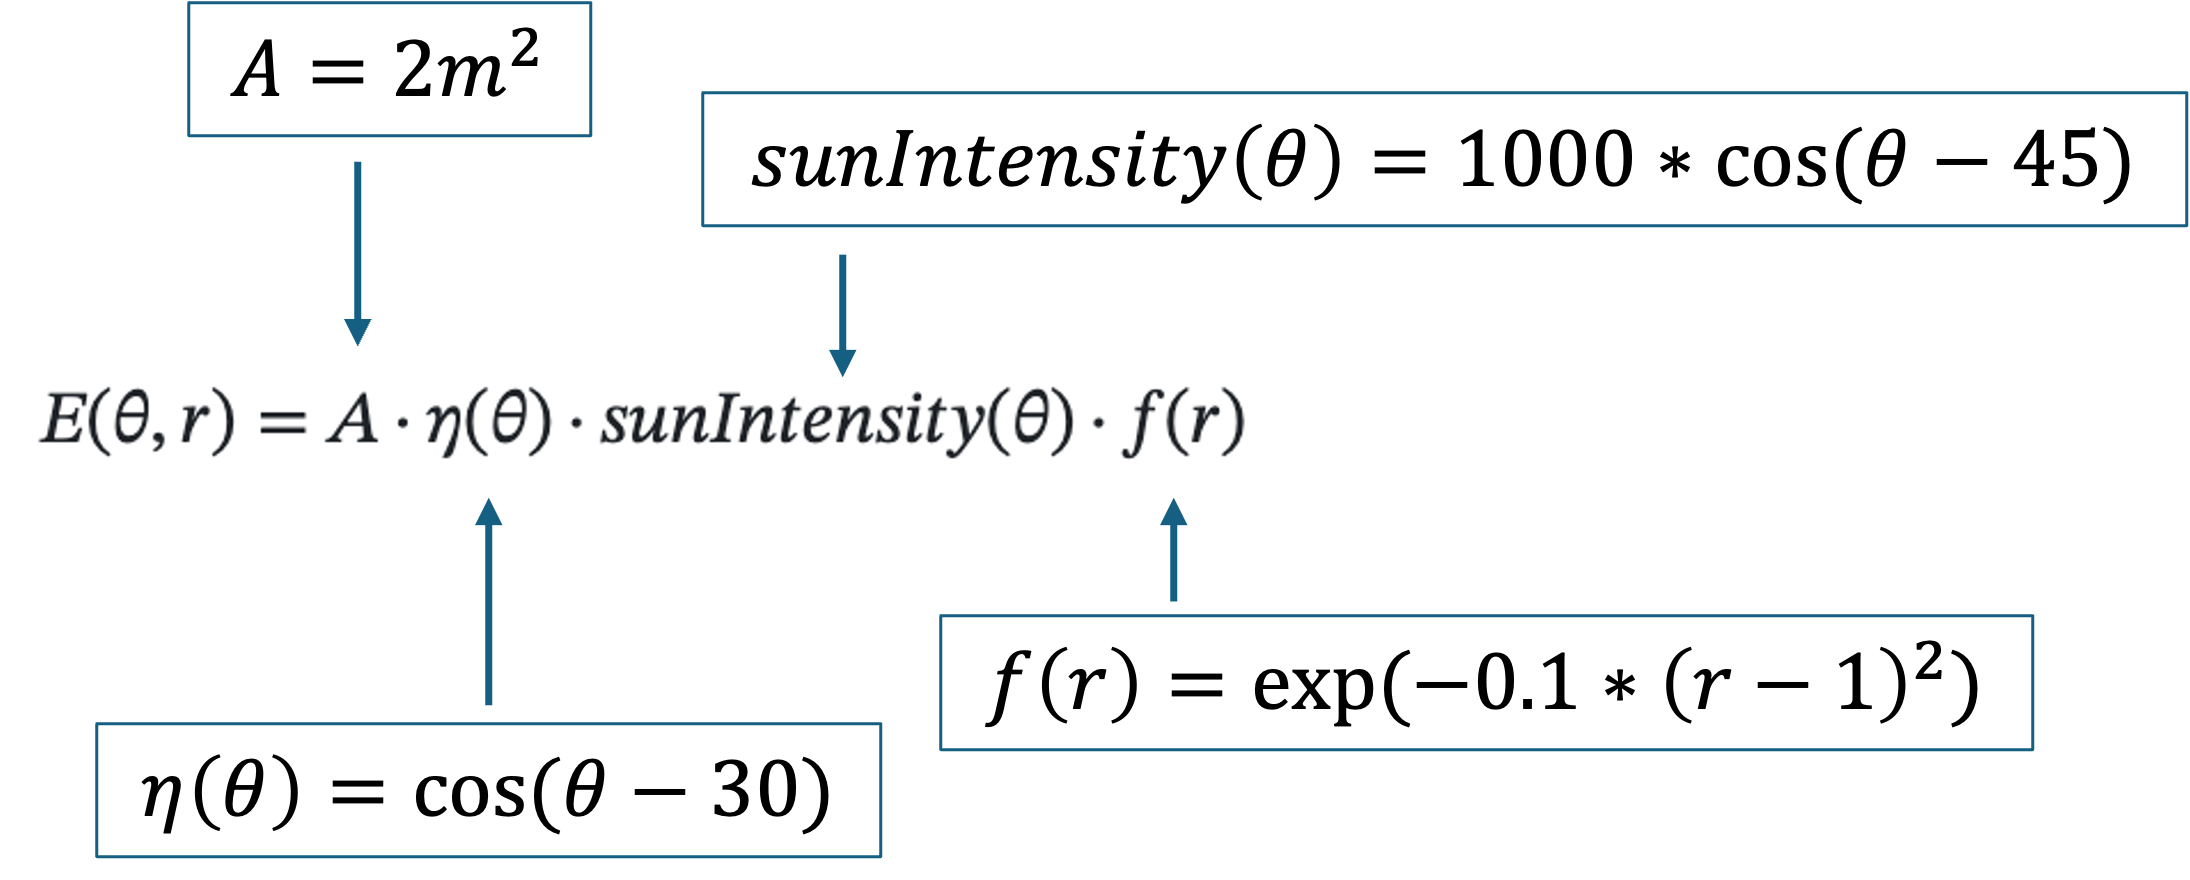

function E = energyOutput(theta, r)

% Define panel area (m^2)
A = 2; 

% Define efficiency based on tilt angle
nu = cosd(theta - 30); 

% Define sunlight intensity
sun_intensity = 1000 .* cosd(theta - 45); 

% Define shape efficiency factor
fr = exp(-0.1 .* (r - 1).^2); 

% Define total energy output
E  = A .* nu .* sun_intensity .* fr;
end


## Task 2: Implement the Optimization Function

Use MATLAB's Optimization Toolbox to find the optimal tilt angle and aspect ratio that MAXIMIZE energy output. This MATLAB [doc page](https://www.mathworks.com/help/optim/ug/problem-based-workflow.html) will be helpful.

% Create maximization problem
solar_problem = optimproblem('ObjectiveSense','maximize'); 

% Define optimization variables
theta = optimvar('theta', 'LowerBound', 0, 'UpperBound', 90);
r = optimvar('r', 'LowerBound', 0.5, 'UpperBound', 4);

% Set the objective
solar_problem.Objective = fcn2optimexpr(@energyOutput, theta, r);

% Set initial guess
x0.theta = 45;  x0.r = 1.5;

% Solve the problem and store results


Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[solution, max_energy] = solve(solar_problem, x0);


## Task 3: Output the Results

Use the appropriate plotting function to plot E(θ, r) and visualize the energy surface. Print the optimal tilt angle and aspect ratio, and corresponding energy output.

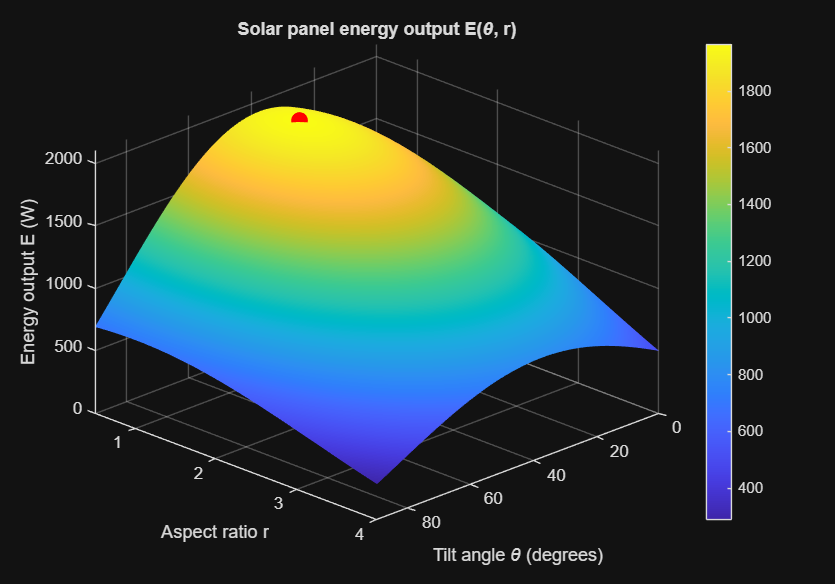

% Create grid values
theta_values = sort(unique([0:1:90, solution.theta]));
r_values     = sort(unique([0.5:0.1:4, solution.r]));
[theta_grid, r_grid]  = meshgrid(theta_values, r_values);

% Calculate energy on the grid
energy_grid    = energyOutput(theta_grid, r_grid);

% Create surface plot
figure('Position', [100, 100, 1000, 700]); 
surf(theta_grid, r_grid, energy_grid); 
shading interp; 
colorbar;
xlim([0 90]);
ylim([0.5 4]);
zlim([0 2100]);

% Label the plot
xlabel('Tilt angle \theta (degrees)');
ylabel('Aspect ratio r');
zlabel('Energy output E (W)');
title('Solar panel energy output E(\theta, r)');
view(135, 30);

% Mark the optimal point
hold on; plot3(solution.theta, solution.r, max_energy, 'r.', 'MarkerSize', 30);

hold off;

% Print results

Optimal tilt angle  : 37.50 degrees


fprintf('Optimal tilt angle  : %.2f degrees\n', solution.theta);

Optimal aspect ratio: 1.00


fprintf('Optimal aspect ratio: %.2f\n',        solution.r);

Maximum energy      : 1965.93 W


fprintf('Maximum energy      : %.2f W\n',       max_energy);

## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning:

What are some limitations of your work?

What are practical next steps?